# TAREA 3

## IE0431 Sistemas de Control - Universidad de Costa Rica, Escuela de Ingeniería Eléctrica

## Diego Alfaro Segura, C20259, grupo 01

clc
clear
close all

## 1) Simulación de sistema

kp = 9; % Kp según carnet
tiempoSimulacion = 20; % Tiempo simulación
out = sim('C20259_DiegoAlfaro_G01.slx',tiempoSimulacion); %comando para simular el DB
syms t s;

### i. Salida y(s)

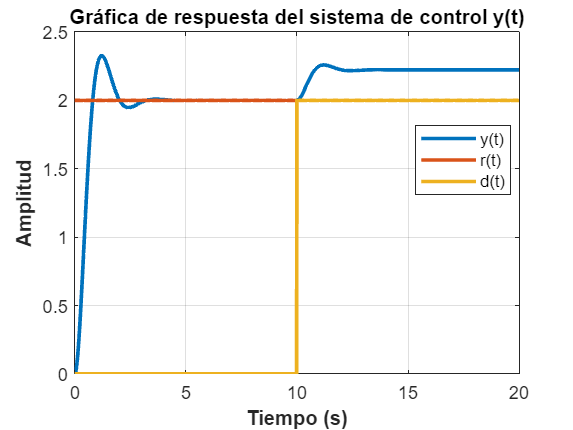

plot(out.y,"LineWidth",2,'DisplayName',"y(t)")
hold on
plot(out.r,"LineWidth",2,'DisplayName',"r(t)")
plot(out.d,"LineWidth",2,'DisplayName',"d(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de respuesta del sistema de control y(t)");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
hold off

### ii. Salida u(s)

plot(out.u, "LineWidth",2, 'DisplayName', "u(t)")
hold on
plot(out.r, "LineWidth",2, 'DisplayName', "r(t)")
plot(out.d, "LineWidth",2, 'DisplayName', "d(t)")
umax = max(out.u.Data)

umax = 18

tumax = out.u.Time(out.u.Data == max(out.u.Data))

tumax = 0

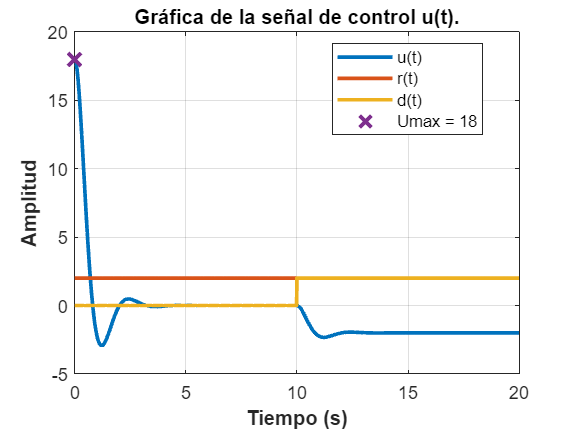

plot(tumax, umax, 'x', 'MarkerSize', 10, "LineWidth", 2, 'DisplayName', ['Umax = ' num2str(umax)])

% Personalización
grid on
legend('Location','best');
title("Gráfica de la señal de control u(t).");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
hold off

### iii) Operando como servomecanismo

tiempo = out.y.Time;
filtroTiempo = (tiempo >= 0) & (tiempo <= 6);
tiempoServo = out.y.Time(filtroTiempo);
yServo = out.y.Data(filtroTiempo);

info = stepinfo(yServo, tiempoServo);
valorFinal = yServo(end);

plot(tiempoServo, yServo,"LineWidth",2,'DisplayName',"y(t)")
hold on

% Tiempo de levantamiento
TiempoLevantamiento = info.RiseTime

TiempoLevantamiento = 0.5459

tnoventaPorciento = tiempoServo(find(yServo >= valorFinal*0.9, 1));  % Tiempo a 90%
tdiezPorciento = tiempoServo(find(yServo >= valorFinal*0.1, 1));     % Tiempo a 10%

plot(tdiezPorciento, 0.1*valorFinal, 'x', 'MarkerSize', 10, "LineWidth", 2, 'DisplayName','10% = (0.1628, 0.2)');
plot(tnoventaPorciento, 0.9*valorFinal, 'x', 'MarkerSize', 10, "LineWidth", 2, 'DisplayName','90% = (0.7087, 1.8)');

plot([tnoventaPorciento; tnoventaPorciento], [0; 0.9*valorFinal], HandleVisibility="off", LineStyle="--", Color="black")
plot([tdiezPorciento; tdiezPorciento], [0; 0.1*valorFinal], HandleVisibility="off", LineStyle="--", Color="black")
plot([tdiezPorciento; tnoventaPorciento], [0.1*valorFinal; 0.1*valorFinal], HandleVisibility="off", Color="black")
text(0.8, 0.1*valorFinal,['tl=' num2str(TiempoLevantamiento) ' s'])

% Tiempo de asentamiento 2%
TiempoAsentamiento = info.SettlingTime

TiempoAsentamiento = 2.6949

tolerancia = 0.02 * valorFinal;
puntoEnBanda = ['Banda = ' '(' num2str(TiempoAsentamiento, 3) ', ' num2str(valorFinal - tolerancia, 3) ')'];
plot(TiempoAsentamiento, valorFinal - tolerancia, 'x', 'MarkerSize', 10, "LineWidth", 2, 'DisplayName', puntoEnBanda);
yline(valorFinal + tolerancia, LineStyle="--", HandleVisibility="off")
yline(valorFinal - tolerancia, LineStyle="--", HandleVisibility="off")
plot([TiempoAsentamiento; TiempoAsentamiento], [0; valorFinal - tolerancia], HandleVisibility="off", LineStyle="--", Color="black")
text(TiempoAsentamiento + 0.1, 1.5, ['ta2%=' num2str(TiempoAsentamiento,3)])

% Mp (%)
Mp = info.Overshoot

Mp = 16.2901

plot(info.PeakTime, info.Peak, 'x', 'MarkerSize', 10, "LineWidth", 2, 'DisplayName','Max = (1.2, 2.326)', Color="green");
plot([info.PeakTime; info.PeakTime], [2; info.Peak], HandleVisibility="off", Color="black")
text(info.PeakTime + 0.2, info.Peak,['Mp=' num2str(Mp,3) '%'])

% IAE
e = out.r - out.y;
Ts = out.u.Time(2) - out.u.Time(1);
IAE = Ts * sum(abs(e.Data),"all")

IAE = 3.2904


% ITSE
ITSE = Ts * sum(e.Time.*power(e.Data,2))

ITSE = 7.5803


% Umax
Umax = max(out.u)

Umax = 18


% Tvur
TVu = sum(abs(out.u.Data(2:end) - out.u.Data(1:end-1)))

TVu = 27.7916


% Error permanente
C1 = kp;
P1 = 1/(s*(s+3));
errorParte3 = s/(1+C1*P1) * 1/s;
errorServoParte3 = limit(errorParte3, s, 0)

$$errorServoParte3 = 0$$

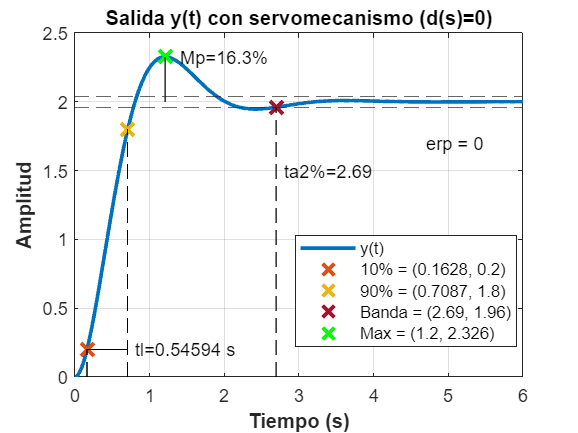

text(4.7, 1.7,['erp = ' char(errorServoParte3)])

% Personalización
grid on
legend('Location','best');
title("Salida y(t) con servomecanismo (d(s)=0)");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
hold off

## iv) Error permanente con Kp = 13 y r(t)=3+t

P2 = 1/(s*(s+3));
C2 = 13;
entrada = 3 + t;
errorServo4 = s/(1+C2*P2) * laplace(entrada);
errorServoParte4 = limit(errorServo4, s, 0)

$$errorServoParte4 = 0.2308$$

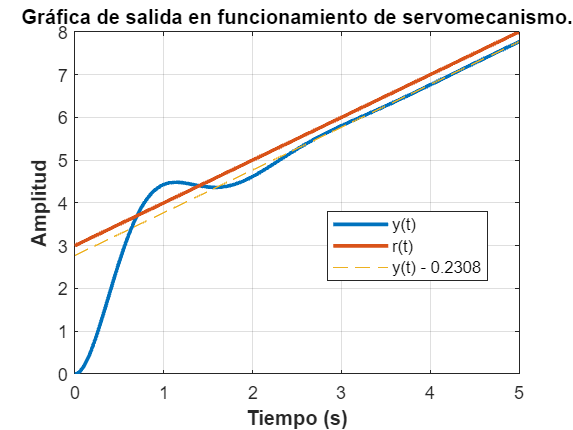


plot(out.y2, "LineWidth",2, 'DisplayName', "y(t)")
hold on
plot(out.r2, "LineWidth",2, 'DisplayName', "r(t)")

% Personalización
grid on
legend('Location','best');
title("Gráfica de salida en funcionamiento de servomecanismo.");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
plot([0;5], [3-errorServoParte4;8-errorServoParte4], LineStyle="--",DisplayName="y(t) - 0.2308")
xlim([0 5]);
hold off

## v) Error permanente con Kp = 13 y d(t)=escalón unitario

perturbacion = 1/s;
errorRegulador5 = -s*P2/(1+C2*P2)*perturbacion;
errorReguladorParte5 = limit(errorRegulador5, s, 0)

$$errorReguladorParte5 = -0.0769$$

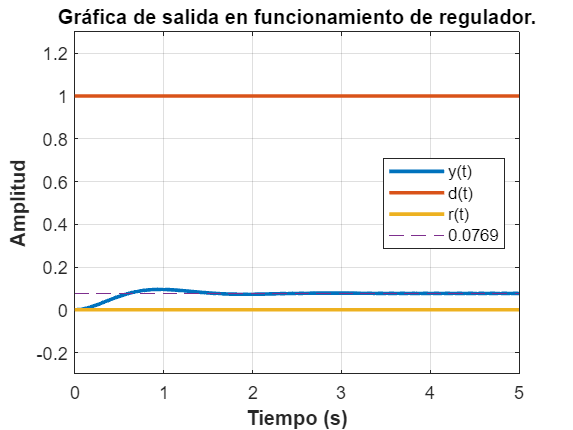



plot(out.y3, "LineWidth",2, 'DisplayName', "y(t)")
hold on
plot(out.d3, "LineWidth",2, 'DisplayName', "d(t)")
plot([0;5], [0;0], "LineWidth",2, 'DisplayName', "r(t)")
plot([0;5], [out.y3.Data(end);out.y3.Data(end)], LineStyle="--",DisplayName=num2str(out.y3.Data(end), 3))

% Personalización 
grid on
legend('Location','best');
title("Gráfica de salida en funcionamiento de regulador.");
xlabel("Tiempo (s)",'FontWeight','bold');
ylabel("Amplitud",'FontWeight','bold');
ylim([-0.3 1.3])
xlim([0 5]);
hold off

### Extra: Verificación de parte 2

s = tf('s');

K = 0.05*9;
T = 0.2;
a = 0.1;
Chi = 1;
Kp = ( (((1+a)/(a*T)) / (2*Chi))^2 *a*T^2 - 1)/K

Kp = 4.5000


C2 = 4.5; % Kp
P2 = K/((T*s+1)*(a*T*s+1));

Myr = C2*P2/(1+C2*P2);
[wn,zeta] = damp(Myr);
zeta

zeta =     1.0000
    1.0000
    1.0000
    1.0000


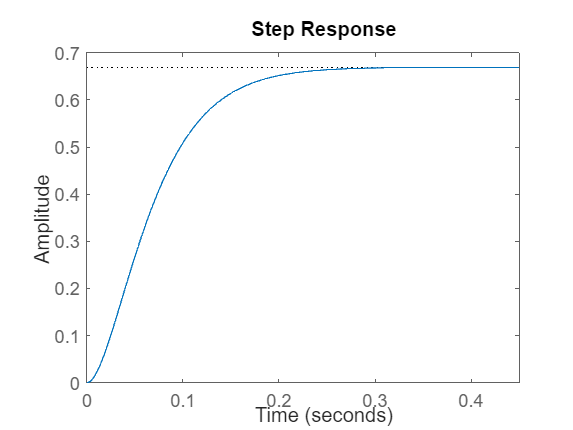

step(Myr)


% Se comenta pues es un poco lento, pero usar en caso 
% de querer verificar la ganancia:
% sisotool(P2,C2)